# Project software:  Selecting MCC data

These utilities  help you read data from the Macbeth Color Checker (MCC).  While largely automated, you do need to be careful.  Sometimes the selection routines miss by a bit; please check as you use.

**Note:** Please make sure you have done a git pull on the psych221 and ISETCam repositories.

## Reading data from the 24 patches

ISETCam has routines to help you retrieve data from a Macbeth color checker (MCC).  The selection routines were designed originally to work with an MCC that looks like this.

scene = sceneCreate;
sceneWindow(scene);

There are many MCCs in the world, however, that have black borders around the patches. Also, many of the images acquired by real cameras are not perfectly squared up with the frame.  I have been updating the methods to handle these cases, but more work can be done.

Here is an an example of an MCC black border.  

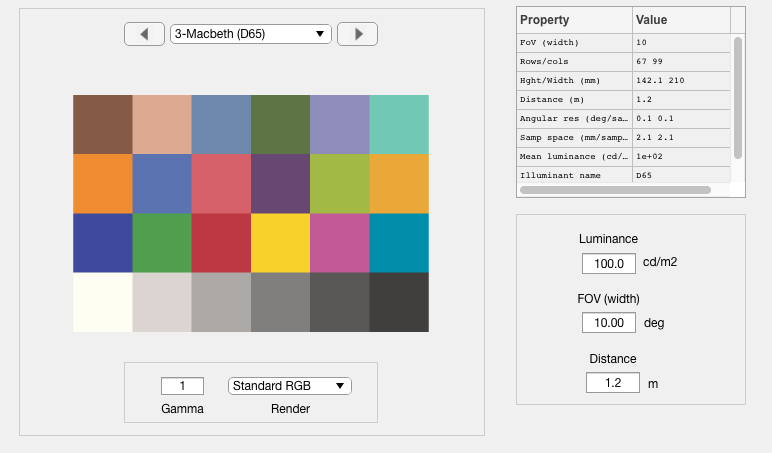

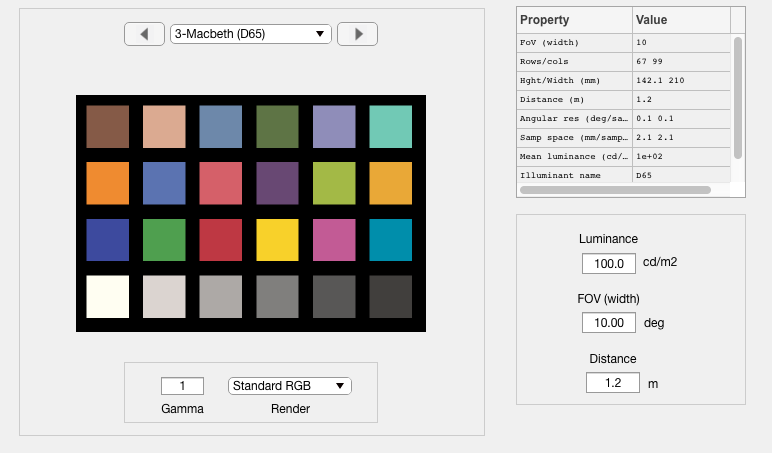

patchSizePixels = 64; wave = (400:10:700); 
blackBorder = true;
scene = sceneCreate('macbeth d65',patchSizePixels,wave,...
    'macbethChart.mat',blackBorder);
sceneWindow(scene);

## Reading data from the patches

ISETCam numbers the patches starting at the upper left corner (brown, (1,1)) and counts down the rows (orange, blue, white).  The white patch at location (4,1) is patch number 4, and the gray series numbers are 4, 8, 12, 16, 20, 24.

The steps to select and read data from a chart are to (a) select the four corner points, (b) visually check the rectangular patches, and (c) retrieve the data from the rectangular regions.   

When the MCC has black borders, we treat the effective patches as shown in these white dashed squares.  To make things work out, you select the corner points as shown by the points in the red circles.

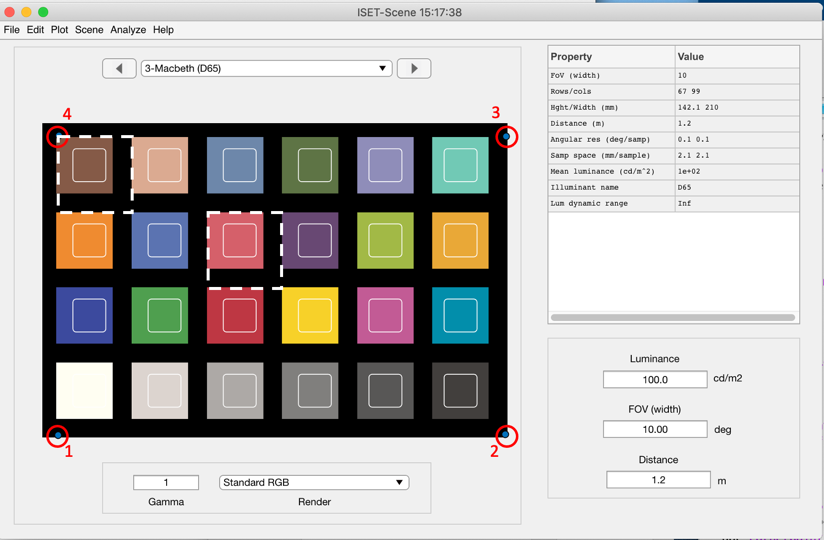

cp = chartCornerpoints(scene);   % Select corners

blackBorder = true;  % Estimate rectangles
[rects, mLocs, pSize] = chartRectangles(cp,4,6,0.5,blackBorder);

chartRectsDraw(scene,rects);  % Visualize the rectangles

Black border



nPixels = round(pSize(1)/5);  % Choose a fraction of the pixels in the patch
fullData = false;             % Return only the mean
meanRadiance = chartRectsData(scene,mLocs,nPixels,fullData);

The meanRadiance data are returned in ISETCam XW format.  This means the spatial position varies down the rows and the wavelength varies across the columns.  We can plot the radiances from each patch this way (not the transpose)

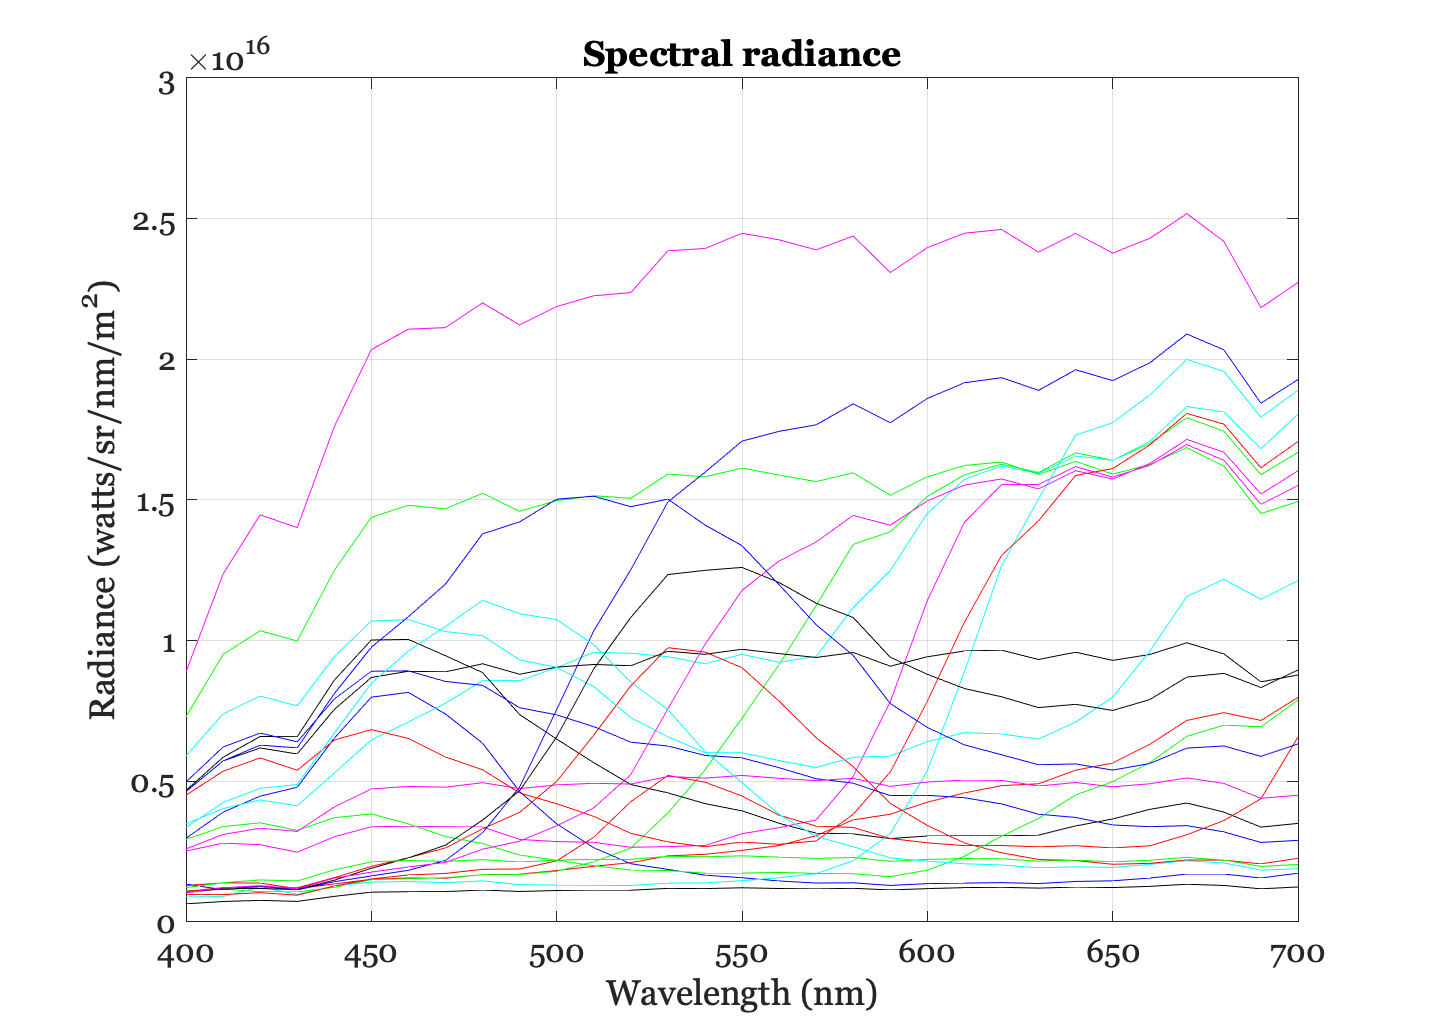

wave = sceneGet(scene,'wave');
plotRadiance(wave,meanRadiance');

## Compute sensor data

The selection method is the same in other ISETCam windows.  In this example, consider the sensor window.  The selection is the same, but the data are more complicated because the sensor data are more complicated.

Compute the sensor data this way.

oi = oiCreate;
oi = oiCompute(oi,scene);
sensor = sensorCreate;
sensor = sensorSet(sensor,'fov',sceneGet(scene,'fov'),oi);
sensor = sensorSet(sensor,'quantization method','10 bit');
sensor = sensorCompute(sensor,oi);
sensorWindow(sensor);

## Select sensor data

Sselect the corner points in the sensor window, and check the rectangle positions.  It is a bit tricky to select the proper corners (sorry).  Also, notice that we use 'sensor', not 'scene' as the argument to chart functions.

cp = chartCornerpoints(sensor);
[rects, mLocs, pSize] = chartRectangles(cp,4,6,0.5,true);

Black border


chartRectsDraw(sensor,rects);
nPixels = round(pSize(1)/5);  % Choose the central 20% of the pixels

And in this case we return the values at all the pixels, not just the mean.  We ask for volts.  It is also possible to ask for 'electrons' or 'dv' (if quantization method is turned on).

fullData = false;   % The mean value of each patch is returned
dataType = 'volts';
meanVolts = chartRectsData(sensor,mLocs,nPixels,fullData,dataType);

## Selecting full data

Up to this point we set fullData to false, and the returned values were the mean levels in each patch.  If you set fullData to true, then the returned values  from each patch will be the data from each point, not just the mean.

fullData = true;         % Data from each pixel in each patch is returned
dataType = 'dv';  % I changed to electrons because I was bored.
electrons = chartRectsData(sensor,mLocs,nPixels,fullData,dataType);

% In this case the format of the data is more complex because of the
% mosaic.  For example, here are the data from the 11th (red) patch at
% (3,3). There are lots of 'red' electrons
redPatch = electrons{11};
r = redPatch(:,1); disp(nanmean(r));

  571.1875



g = redPatch(:,2); disp(nanmean(g));

   44.1000



b = redPatch(:,3); disp(nanmean(b));

    30




% In the blue patch (3,1) there are more blue electrons
bluePatch = electrons{3};
r = bluePatch(:,1); disp(nanmean(r));

   66.3750



g = bluePatch(:,2); disp(nanmean(g));

   46.4250



b = bluePatch(:,3); disp(nanmean(b));

  119.4400



## Without black borders

When doing simulations we often use the MCC without black borders. Here is a picture of how to select the corner points when the MCC has no black border.

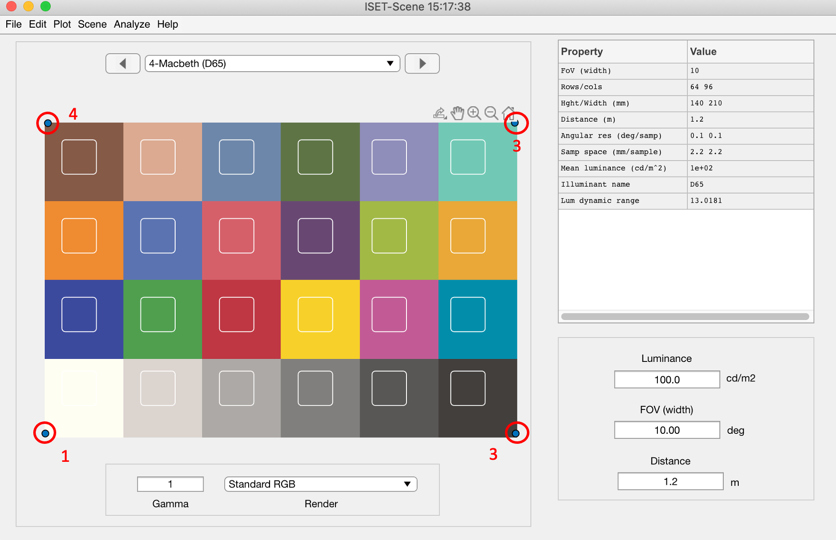

% A little bigger than default 
patchSize = 32;   
scene = sceneCreate('macbeth d65',patchSize);
sceneWindow(scene);

% This convenience switch indicates the MCC is the whole image
wholeImage = true;    
cp = chartCornerpoints(scene, wholeImage);
[rects, mLocs, pSize] = chartRectangles(cp,4,6,0.5,true);

Black border


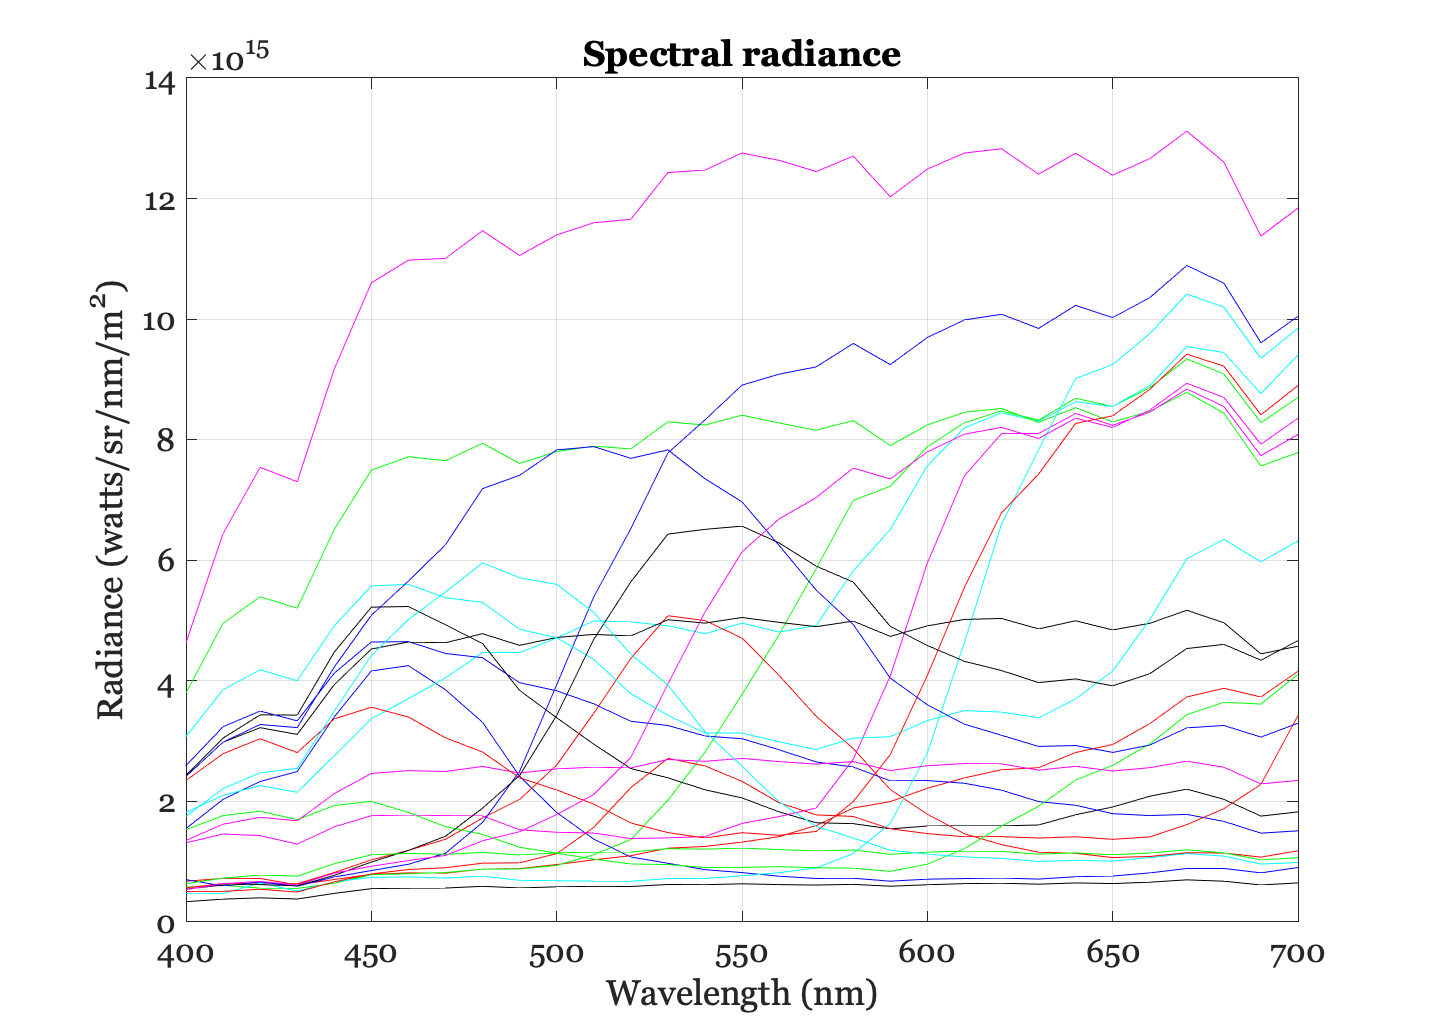

chartRectsDraw(scene,rects);
nPixels = round(pSize(1)/5);  % Choose the central 20% of the pixels
fullData = false;
meanRadiance = chartRectsData(scene,mLocs,nPixels,fullData);
plotRadiance(sceneGet(scene,'wave'),meanRadiance');

## Natural reflectance chart: for simulation

While important for industry, the MCC is a small and unrepresentative sample.  For other simulation projects we use a larger number of surface reflectances and lights.  ISETCam includes a method for creating charts with many more natural reflectances.

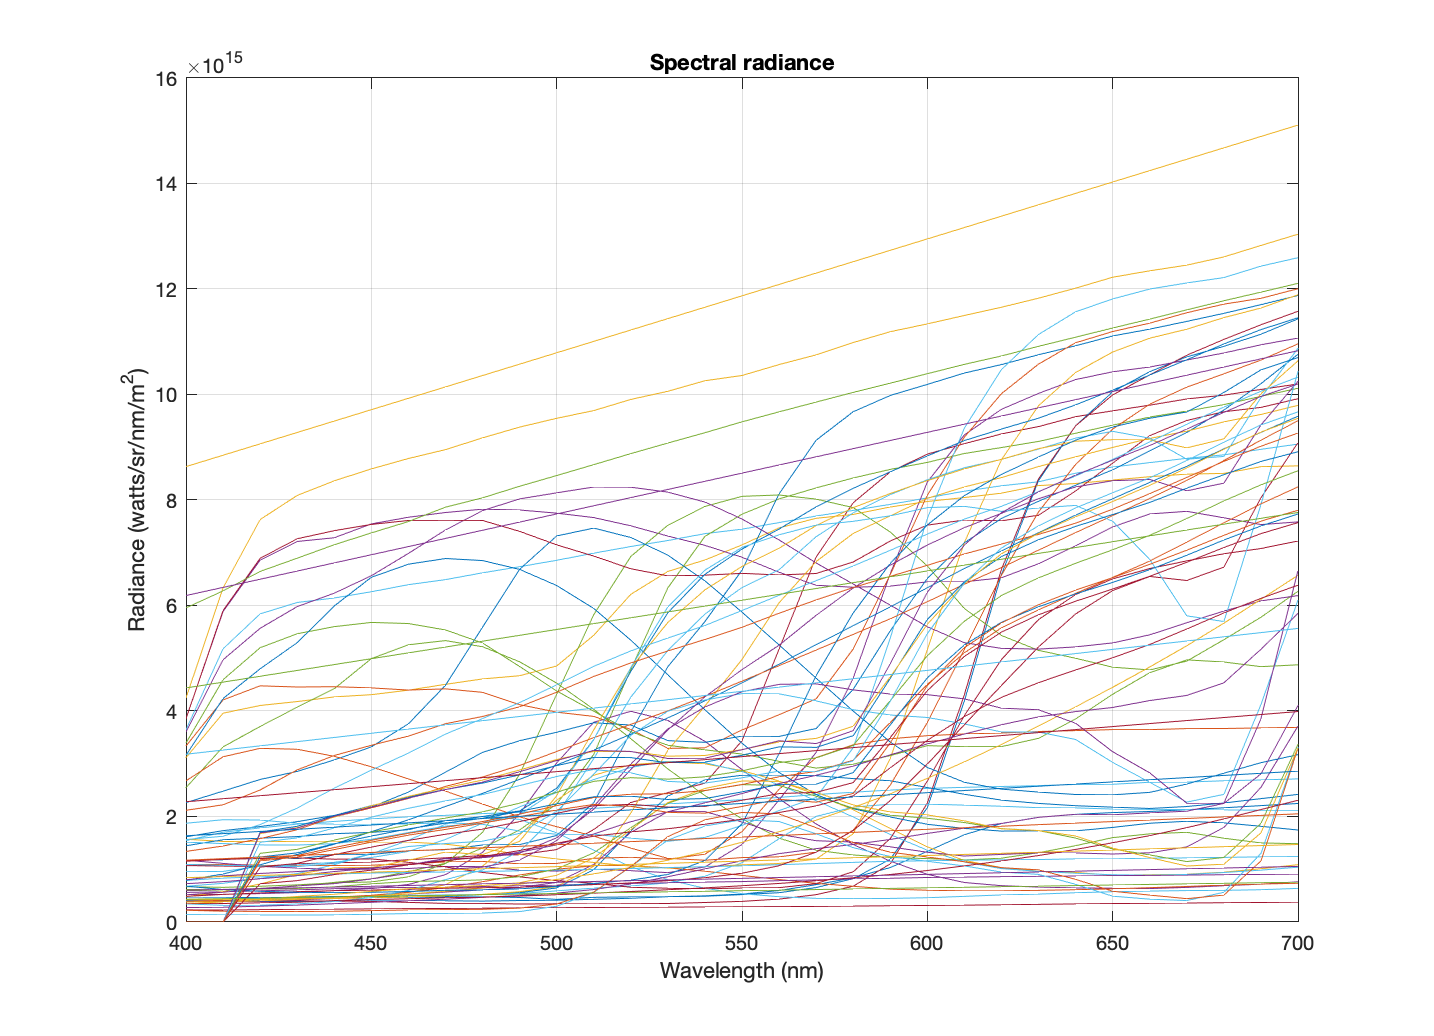

% This chart is a random sample of surface reflectances stored in ISETCam.
% You can read the documentation to see how to carefully control the set of
% surfaces in the chart
scene = sceneCreate('reflectance chart');
sceneWindow(scene);

% You can select the data in this more complex chart using the same
% methods as the MCC.
wholeImage = true;
cp = chartCornerpoints(scene, wholeImage);
[rects, mLocs, pSize] = chartRectangles(cp,10,11,0.3);
chartRectsDraw(scene,rects);
meanRadiance = chartRectsData(scene,mLocs,pSize(1)/5);
plotRadiance(sceneGet(scene,'wave'),meanRadiance');